# Study on Torque

## Initialization

clear
close all
clc

addpath(genpath('Data'));
addpath(genpath('Figures'));
addpath(genpath('Modular Models'));
addpath(genpath('Scripts'));

motor_params;

## Data Loading and Preparation

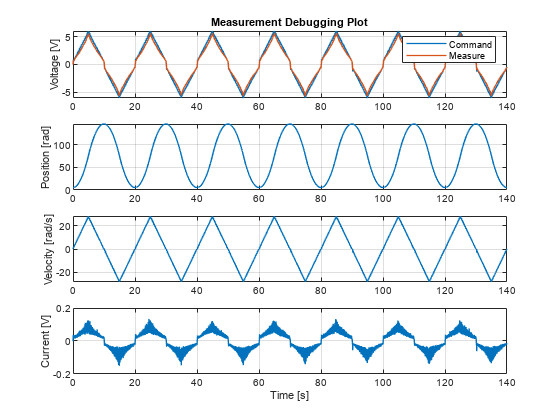

% load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\Motor_Voltage_Chirp_Experiment.mat');
load('D:\Data\_PROGETTI\PRJ_SMART_SERVO\MATLAB\Data\PID_Velocity_Triangle_Experiment.mat');
dataset = exp_to_std(data); clear data;

dataset.velocity = sgolayfilt(gradient(dataset.position)/1e-3, 1, 21);
dataset.acceleration = sgolayfilt(gradient(dataset.velocity)/1e-3, 1, 21);

dataset.current_f1 = sgolayfilt(dataset.current, 3, 11);
dataset.current_f2 = sgolayfilt(dataset.current_f1, 3, 11);
dataset.current_f3 = sgolayfilt(dataset.current_f2, 3, 11);


fig = figure();

subplot(4,1,1), plot(dataset.time, dataset.command*6, dataset.time, dataset.voltage, 'LineWidth', 1)
lgd = legend('Command', 'Measure');
ylabel('Voltage [V]')
grid on

title('Measurement Debugging Plot')

subplot(4,1,2), plot(dataset.time, dataset.position, 'LineWidth', 1)
ylabel('Position [rad]')
grid on

subplot(4,1,3), plot(dataset.time, dataset.velocity, 'LineWidth', 1)
ylabel('Velocity [rad/s]')
grid on

subplot(4,1,4), plot(dataset.time, dataset.current, 'LineWidth', 1)
ylabel('Current [V]'), xlabel('Time [s]')
grid on

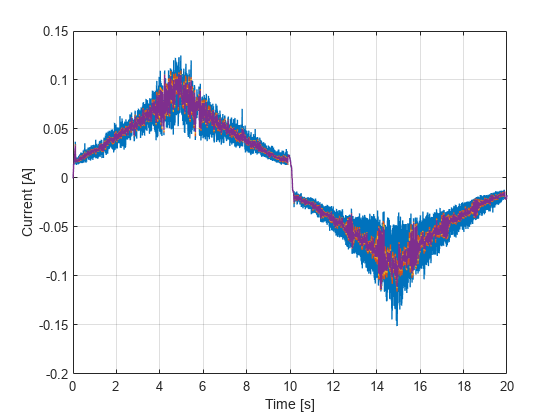

figure()

plot(dataset.time, [dataset.current, dataset.current_f1, dataset.current_f2, dataset.current_f3], 'LineWidth', 1)
xlabel('Time [s]'), ylabel('Current [A]')
xlim([0, 20])
grid on

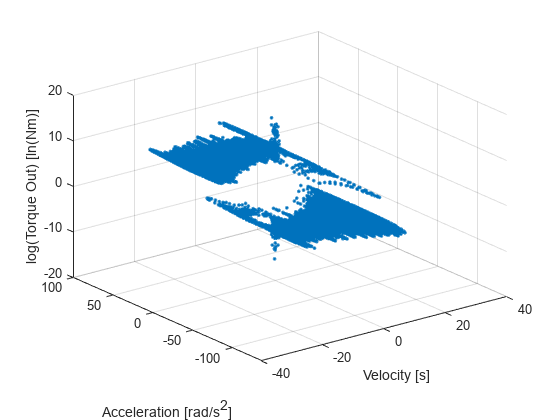

Tout = motor.Kg*(dataset.voltage.*dataset.current_f3 - motor.Ra*dataset.current_f3.^2)./dataset.velocity;
Tout_f = sgolayfilt(Tout, 3, 51);
Tout(abs(Tout) >= 1e3) = 0;

T = sign(Tout).*log(abs(Tout));

figure()

plot3(dataset.velocity, dataset.acceleration, T, ' .')
grid on
xlabel('Velocity [s]'), ylabel('Acceleration [rad/s^2]'), zlabel('log(Torque Out) [ln(Nm)]')

% zlim([1e-12, 1e3]), set(gca, 'ZScale', 'log')

## 3D Plot of Motor Torque

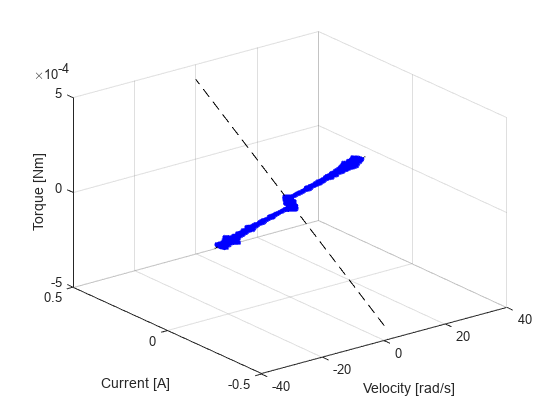

line1.current = -0.5:1e-1:0.5;
line1.torque = motor.Kphi_0*line1.current;
line1.velocity = zeros(size(line1.current));

line2.velocity = -30:1e-2:30;
line2.torque = (motor.Tc*sign(line2.velocity) + motor.Be*line2.velocity/motor.Kg);
line2.current = line2.torque/motor.Kphi_0;

stribeck = (motor.Tc + motor.Tc*exp(-(dataset.velocity/(motor.Kg*motor.Wsb)).^2)).*sign(dataset.velocity) + motor.Be*dataset.velocity/motor.Kg;


figure()
plot3(line1.velocity, line1.current, line1.torque, 'k--');
hold on
plot3(line2.velocity, line2.current, line2.torque, 'k--');
plot3(dataset.velocity, dataset.current_f3, stribeck, ' b.');
grid on
xlabel('Velocity [rad/s]'), ylabel('Current [A]'), zlabel('Torque [Nm]')

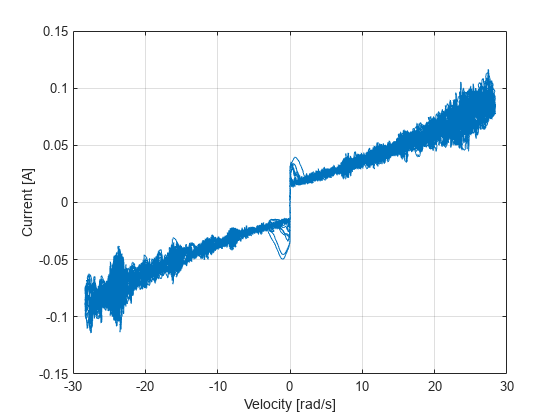

figure()

plot(dataset.velocity, dataset.current_f3)
grid on
xlabel('Velocity [rad/s]'), ylabel('Current [A]')